clear
clc
close all
% Hello, this script calculates a steerable DMA beampattern 
% based on "Steering Study of Linear Differential Microphone Arrays". 

% Only works for distinct nulls right now (Q has other equation for null multiplicity)

% To-do:
% Calculate WNG

% Order of ideal function
N = 2

N = 2


% Number of microphones M > N 
M = N +1

M = 3

%M = 15;
 
% Steering of main lobe
steerAng =65.01

steerAng = 65.0100

xs = cosd(steerAng);                 

% Minimum and maximum frequency
f_min = 0;
f_max = 24e3;

% Signal frequency to design filter (Hz)
%f = 8e3;       
%f = (f_max-f_min)/2
f = f_max;

% Frequency sweep list
freqs = linspace(f_min, f_max, (f_max-f_min)/(100)+1)

freqs =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800        1900        2000        2100        2200        2300        2400        2500        2600        2700        2800        2900        3000        3100        3200        3300        3400        3500        3600        3700        3800        3900        4000        4100        4200        4300        4400        4500        4600        4700        4800        4900



% Speed of sound (m/s)
%c = 343;  
c = 1496;

% Microphone spacing (m)
d = 0.01;
%d = (c/f_max)*0.1

% Temporary null vector, dim = N - 1
nullAngles = [flip((steerAng-180/N:-180/N:0)) (steerAng+180/N:180/N:180)]' 

nullAngles = 155.0100


%%%%
% nullAngles = [0 115 155]'   %FSDLMA-III
% N = 4;                      %FSDLMA-III
% steerAng = 75               %FSDLMA-III
% xs = cosd(steerAng)         %FSDLMA-III
%%%%

% Concat with steering angle
x = [xs; cosd(nullAngles)]; 

% Set up linear system of equations
epsi = diag(0:N);
Q = cat(1, [(x(1).^(0:N)); (x(1).^(0:N)*epsi)], x(2:end).^(0:N));

% Inverse with constraint function
a = Q\eye(length(Q),1);

% Determine last null
xN = - a(end-1)/a(end) - sum(x(2:end))

xN = 1.7513


% Determined null vector
x = [x; xN]      

x =     0.4225
   -0.9064
    1.7513



% % Phase vector of microphone array
% D = exp((-1i*2*pi*f*d*(0:M-1).*x)/c);
% 
% % Filter weights
% if M == N + 1
%     h = D\eye(N+1,1);
% else
%     h = D'*inv(D*D')*eye(N+1,1);
% end

% Normalise weights
%h = h / sum(abs(h));

% Generate input
ang_resolution = 360;
thetas = linspace(0, 2*pi,ang_resolution);
output = zeros(length(freqs),length(thetas));

for k=1:length(freqs)
    %D = exp((-1i*2*pi*freqs(ceil(k/10)*10)*d*(0:M-1).*x)/c); % Every 10th in freqs
    D = exp((-1i*2*pi*freqs(k)*d*(0:M-1).*x)/c);
    if M == N + 1
        h = D\eye(N+1,1);
    else
        h = D'*inv(D*D')*eye(N+1,1);
    end

    Y = exp(-1i*2*pi*freqs(k)*d*(0:M-1).*cos(thetas(:))/c)'; 
    output(k,:) = h'*Y;
end


bp = abs(output);
mindB = -50;
logOutput = mag2db(bp);
logOutput(logOutput < mindB) = mindB;

save('bfweights.mat', 'h', 'steerAng')

## Call plot-functions

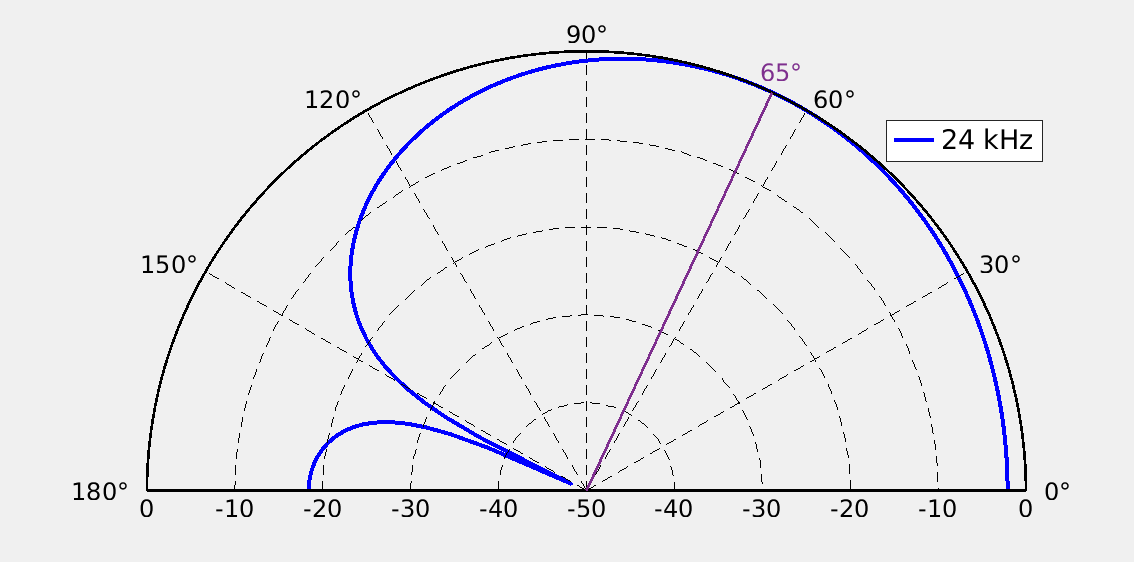

indexHz = find(freqs==1e3); % Find design frequency in sweep list
figure(1)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 20])

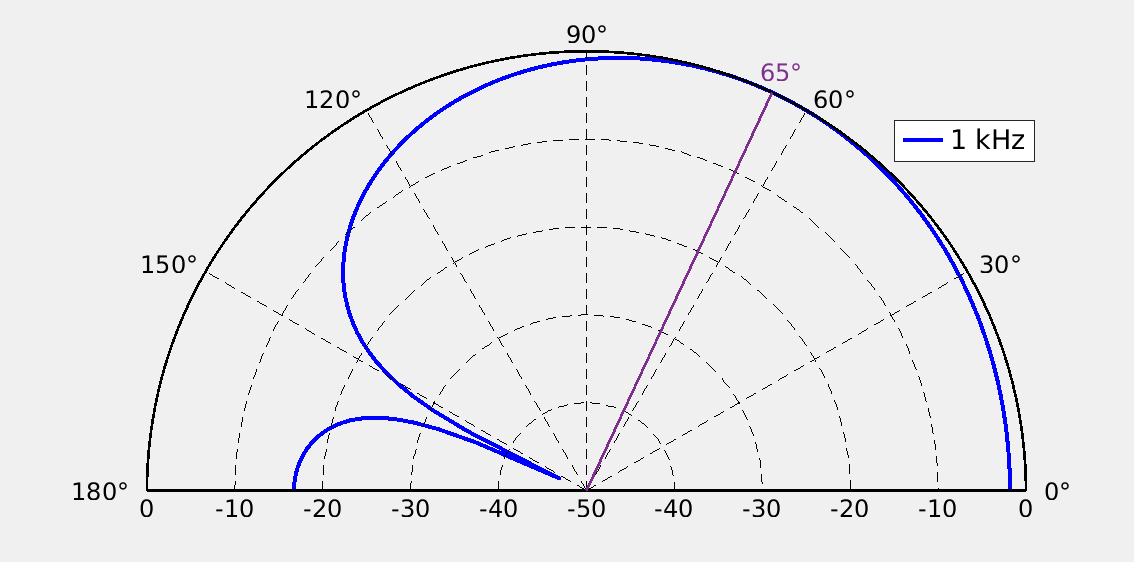

circPlot(freqs(indexHz), thetas, logOutput(indexHz,:), steerAng)

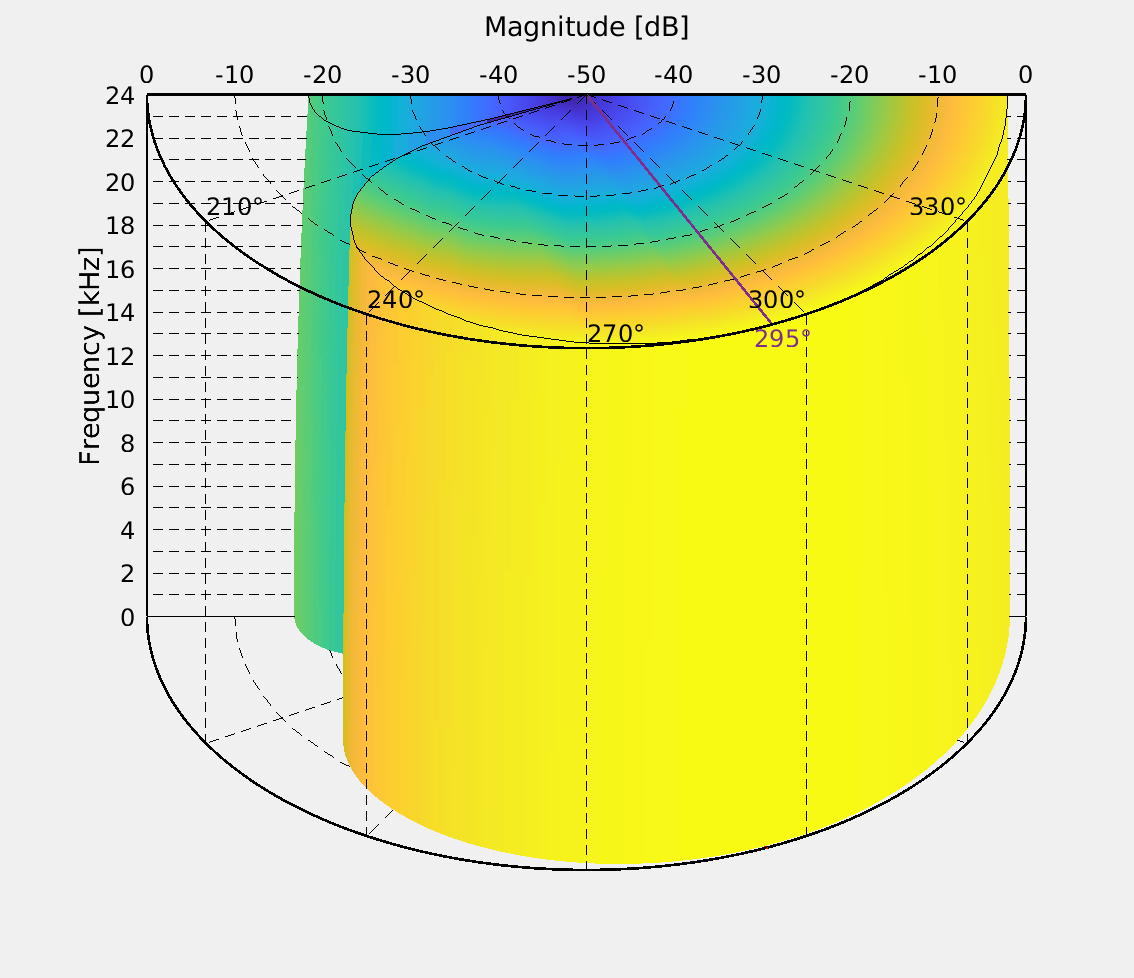

%exportgraphics(gcf,'DMAHz.pdf')

figure(2)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 31])

cylindricalPlot(freqs, thetas, logOutput, steerAng)

%exportgraphics(gcf,'DMA3D.pdf')
